,Get operating point

% run trimming.m file
run('linear_analysis/trimming.m')

Optimizing to solve for all desired dx/dt=0, x(k+1)-x(k)=0, and y=ydes.
 
(Maximum Error)  Block
 ---------------------------------------------------------
(2.76707e-03) main_to_linearize/Drone Dynamics/Actuator Dynamics/by_actuator_resp
(3.02769e-12) main_to_linearize/Drone Dynamics/Actuator Dynamics/Transfer Fcn (with initial outputs)1/State Space
(3.02769e-12) 

Linearize model from rate input to rate output

mdl = 'main_to_linearize'

mdl = 'main_to_linearize'

io(1) = linio('main_to_linearize/att_control/pitch_rate', 1, 'input')


1x2 vector of Linearization IOs: 
--------------------------
1. Linearization input perturbation located at the following signal:
- Block: main_to_linearize/att_control/pitch_rate
- Port: 1
2. Linearization output measurement located at the following signal:
- Block: main_to_linearize/Drone Dynamics/w_b_comp
- Port: 2
- Signal Name: w_y


io(2) = linio('main_to_linearize/Drone Dynamics/w_b_comp', 2, 'output')


1x2 vector of Linearization IOs: 
--------------------------
1. Linearization input perturbation located at the following signal:
- Block: main_to_linearize/att_control/pitch_rate
- Port: 1
2. Linearization output measurement located at the following signal:
- Block: main_to_linearize/Drone Dynamics/w_b_comp
- Port: 2
- Signal Name: w_y



G_rate = linearize(mdl, io, op)


G_rate =
 
  A = 
                    p,q,r (1)     p,q,r (2)  bx_actuator_  bx_actuator_  by_actuator_  by_actuator_  Transport De  Transport De
   p,q,r (1)                0    -6.131e-36         224.1    -1.831e+04             0             0     2.051e+04             0
   p,q,r (2)        6.131e-36             0             0             0         224.1    -1.831e+04             0     2.051e+04
   bx_actuator_             0             0        -13.13        -72.64             0             0             0             0
   bx_actuator_             0             0             1             0             0             0             0             0
   by_actuator_             0             0             0             0        -13.13        -72.64             0             0
   by_actuator_             0             0             0             0             1             0             0             0
   Transport De             0             0       -0.8738         71.42             0

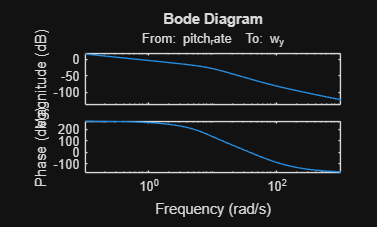

bode(G_rate)

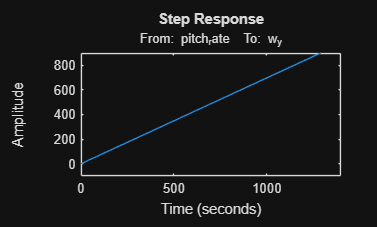

step(G_rate)

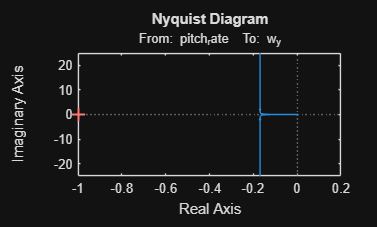

nyquist(G_rate)

% [num, den] = ss2tf(G_rate.A, G_rate.B, G_rate.C, G_rate.D)
% s = tf('s')
% G_rate_tf = tf(num, den) * exp(-0.2*s)
% [A,B,C,D] = tf2ss(G_rate_tf.Numerator{1}, G_rate_tf.Denominator{1})
% G_rate = ss(A,B,C,D) 

Control System Designer

controlSystemDesigner(G_rate)

Disk Margin Check

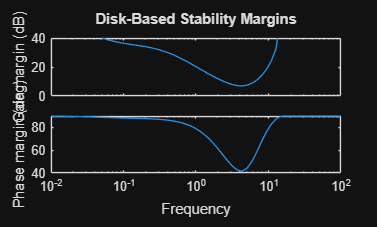

s = tf('s');
format long g;
C = (3.6517 * (s + 0.04375)) / s;

diskmarginplot(C*G_rate)

diskmargin(C*G_rate)

ans = struct with fields:
           GainMargin: [0.448935229005129 2.22749282166175]
          PhaseMargin: [-41.64601653519 41.64601653519]
           DiskMargin: 0.760647901940026
           LowerBound: 0.760647901940026
           UpperBound: 0.760647901940026
            Frequency: 4.19233571131972
    WorstPerturbation: [1×1 ss]



G_cl = minreal(feedback(C * G_rate, 1))

4 states removed.

G_cl =
 
  A = 
               x1          x2          x3          x4          x5
   x1      -16.09      0.9388      -36.16        28.7      -52.66
   x2  -8.169e-05       351.9  -1.351e+04   1.071e+04       10.78
   x3   0.0003888      -265.4   1.018e+04       -8064      -23.06
   x4   -0.001691      -348.3   1.336e+04  -1.058e+04       1.794
   x5       2.251      -1.304       50.01      -39.65       20.28
 
  B = 
       pitch_rate
   x1    0.002764
   x2   4.654e-07
   x3  -1.769e-05
   x4    1.41e-05
   x5  -0.0001362
 
  C = 
              x1         x2         x3         x4         x5
   y1  1.208e-11       2.04     -1.859     -2.412  -0.001417
 
  D = 
       pitch_rate
   y1           0
 
Continuous-time state-space model.


bw_rad = bandwidth(G_cl)

bw_rad =           5.30951110496212
